# Calcium transients in control and Cx26 cKO cochlea SGNs with NBQX

% room temp, 6K+ ACSF, dissected at p5-p6, 16-24 hours in vitro
% tecta-cre;Cx26fl/fl;snap25-gc6 and tecta-cre;cx26fl/+;snap25-gc6 +
% cx26flfl; snap25-gc6

defaultDir = 'F:\Calvin\Spontaneous activity in GJB2\SGN calcium imaging'

defaultDir = 'F:\Calvin\Spontaneous activity in GJB2\SGN calcium imaging'

cd(defaultDir);


% This analysis was mean IHC calcium transients with individual cell ROIs 


tectacx1 = load('20191216 exp312 tecta cx26flfl snap25gc6 mouse 3 prep 1 NBQX 10 min_SGNdata.mat');
tectacx2 = load('20191216 exp312 tecta cx26flfl snap25gc6 mouse 7 prep 1 NBQX 10 min_SGNdata.mat');
tectacx3 = load('20191216 exp312 tecta cx26flfl snap25gc6 mouse 7 prep 2 NBQX 10 min_SGNdata.mat');
tectacx4 = load('20191219 exp315 mouse 1 prep 2 tecta cx26flfl nbqx 10 min_SGNdata.mat');

color1 = 'k';
color2 = 'g';
markSz = [0.1 20];
% calcium event frequency with NBQX

preF = [tectacx1.SGNstruct.meanFreqPre,tectacx2.SGNstruct.meanFreqPre,tectacx3.SGNstruct.meanFreqPre,tectacx4.SGNstruct.meanFreqPre];
cx26F = [tectacx1.SGNstruct.meanFreqPost,tectacx2.SGNstruct.meanFreqPost,tectacx3.SGNstruct.meanFreqPost,tectacx4.SGNstruct.meanFreqPost];

conditions = {'baseline','+ NBQX'};
ylbl1 = 'Calcium events per minute';
dim = [1 2];
[fig1 h p] = compare2_2(preF,cx26F,conditions,ylbl1,dim,markSz, color1,color2);

   1.8187e-05



p

p = 1.8187e-05

ylim([0 2]);

subP = handleTheSubplot({fig1,fig1,fig1},[1 3]);
figQuality(subP,gca,[3.5 2])

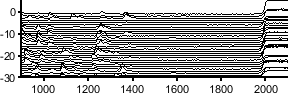


% plot raster with NBQX addition
n = size(tectacx1.SGNstruct.ROIdF,2);
t = 2100;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(tectacx1.SGNstruct.ROIdF(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
xlim([900 2100])
figQuality(gcf,gca,[3 1])

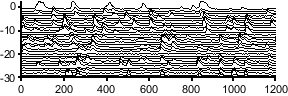

% Control recordings
con1 = load('20191219 exp315 mouse 4 prep 2 cx26flfl 10 min nbqx_SGNdata.mat');

% plotting rasters baseline
n = size(con1.SGNstruct.ROIdF,2);
t = 1200;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con1.SGNstruct.ROIdF(1:t,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

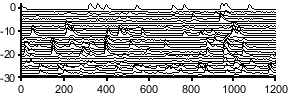


n = size(tectacx3.SGNstruct.ROIdF,2);
t = 1200;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(tectacx3.SGNstruct.ROIdF(1:t,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

% quantification of spontaneous activity patterns, correlation


con1 = load('20191219 exp315 mouse 4 prep 2 cx26flfl 10 min nbqx_SGNdata.mat');
con2 = load('20200301 exp322 mouse 1 prep 2 tecta cx26fl+ snap25-gc6 10 min spont_SGNdata.mat');
con3 = load('20191219 exp315 mouse 6prep 2 cx26flfl 10 min spont_SGNdata.mat'); % this one is not great, clear outlier

tectacx1 = load('20191216 exp312 tecta cx26flfl snap25gc6 mouse 3 prep 1 NBQX 10 min_SGNdata.mat');
tectacx2 = load('20191216 exp312 tecta cx26flfl snap25gc6 mouse 7 prep 1 NBQX 10 min_SGNdata.mat');
tectacx3 = load('20191216 exp312 tecta cx26flfl snap25gc6 mouse 7 prep 2 NBQX 10 min_SGNdata.mat');
tectacx4 = load('20191219 exp315 mouse 1 prep 2 tecta cx26flfl nbqx 10 min_SGNdata.mat');
tectacx5 = load('20191219 exp315 mouse 1 prep 1 tecta cx26flfl mrs2500 10 min_SGNdata.mat');

% frequency
controlF = [con1.SGNstruct.meanFreq,con2.SGNstruct.meanFreq,con3.SGNstruct.meanFreq]

controlF =     1.5942    1.2826    0.8882


cx26F = [tectacx1.SGNstruct.meanFreq,tectacx2.SGNstruct.meanFreq,tectacx3.SGNstruct.meanFreq,tectacx4.SGNstruct.meanFreq,tectacx5.SGNstruct.meanFreq]

cx26F =     1.4393    1.3633    1.3355    1.4015    1.2111



conditions = {'Control','Cx26 cKO'};
ylbl1 = 'Events per minute';
dim = [1 2];
[fig1 h p2] = compare2(controlF,cx26F,conditions,ylbl1,dim);

   0



p2

p2 = 0.7857

ylim([0 2]);

% calcium event width - mean
controlW = [con1.SGNstruct.meanWid,con2.SGNstruct.meanWid,con3.SGNstruct.meanWid];
cx26W = [tectacx1.SGNstruct.meanWid,tectacx2.SGNstruct.meanWid,tectacx3.SGNstruct.meanWid,tectacx4.SGNstruct.meanWid,tectacx5.SGNstruct.meanWid]

cx26W =     8.6843    8.1559    7.7127    8.5061    8.4317


dim = [1 2];
ylbl1 = 'Duration (s)';
[fig2 h p3]= compare2(controlW,cx26W,conditions,ylbl1,dim);

   0



p3

p3 = 1

ylim([0 10]);

controlAmp = [con1.SGNstruct.meanAmp,con2.SGNstruct.meanAmp,con3.SGNstruct.meanAmp]*100

controlAmp =   115.4611  105.8759   56.3191


cx26Amp = [tectacx1.SGNstruct.meanAmp,tectacx2.SGNstruct.meanAmp,tectacx3.SGNstruct.meanAmp,tectacx4.SGNstruct.meanAmp,tectacx5.SGNstruct.meanAmp]*100

cx26Amp =    94.1448   60.3249   91.2289   63.1922   50.7061


ylbl1 = 'Mean amplitude (%dF/F)';
[fig4 h p1] = compare2(controlAmp,cx26Amp,conditions,ylbl1,dim);

   0



p1

p1 = 0.3929

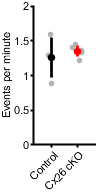

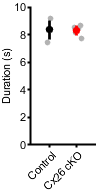

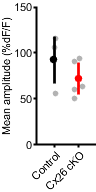


ylim([0 150]);

subP = handleTheSubplot({fig1,fig2,fig4},[1 3]);

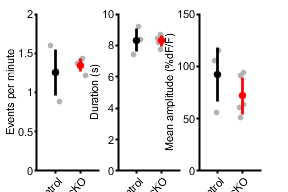

figQuality(subP,gca,[3 2])


[CorrP CorrA h] = fdr_BH([p2,p3],0.05)

CorrP =      1     1


CorrA =     0.0250    0.0500


h = 2×1 logical array
   0
   0


## mean correlation

ConCor1 = corr(con1.SGNstruct.ROIdF(1:1200,:));
meanConCor1 = prctile(ConCor1,80,'all'); 
ConCor2 = corr(con2.SGNstruct.ROIdF(1:1200,:));
meanConCor2 = prctile(ConCor2,80,'all'); 
ConCor3 = corr(con3.SGNstruct.ROIdF(1:1200,:));
meanConCor3 = prctile(ConCor3,80,'all'); 

ckoCor1 = corr(tectacx1.SGNstruct.ROIdF(1:1200,:));
meanckoCor1 = prctile(ckoCor1,80,'all'); 
ckoCor2 = corr(tectacx2.SGNstruct.ROIdF(1:1200,:));
meanckoCor2 = prctile(ckoCor2,80,'all'); 
ckoCor3 = corr(tectacx3.SGNstruct.ROIdF(1:1200,:));
meanckoCor3 = prctile(ckoCor3,80,'all'); 
ckoCor4 = corr(tectacx4.SGNstruct.ROIdF(1:1200,:));
meanckoCor4 = prctile(ckoCor4,80,'all'); 
ckoCor5 = corr(tectacx5.SGNstruct.ROIdF(1:1200,:));
meanckoCor5 = prctile(ckoCor5,80,'all');

conCor = [meanConCor1,meanConCor2,meanConCor3]

conCor =     0.4312    0.5898    0.6005


ckoCor = [meanckoCor1,meanckoCor2,meanckoCor3,meanckoCor4,meanckoCor5]

ckoCor =     0.3771    0.3594    0.3671    0.3837    0.4328



ylbl1 = 'Correlation coefficient';
[fig5 h p1] = compare2(conCor,ckoCor,conditions,ylbl1,dim);

   0



p1

p1 = 0.0714

ylim([0 1])
[h p2] = ttest2(conCor,ckoCor)

h = 1

p2 = 0.0114

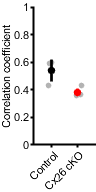


subP = handleTheSubplot({fig1,fig2,fig4,fig5},[1 4]);

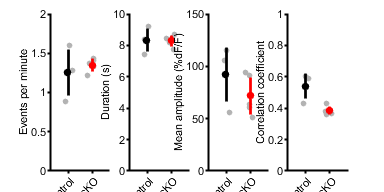

figQuality(subP,gca,[4 2])